# Relatório de Atividade 13 - Métodos *Markov Chain Monte Carlo*

*Débora Nunes Pinto de Oliveira*

*Prof. Antonio Marcus, Estimação e Identificação de Sistemas 21.2*

*23 de Novembro de 2021*

Esse documento tem por objetivo descrever o método de estimação probabilística de Monte Carlo em conjunto com cadeias de Markov para a identificação de uma planta desconhecida. O valor final dos parâmetros estimados pelo método MCMC é a espectativa da distribuição de probabilidade das amostras candidatas. A fim de comparação, o problema proposto também foi resolvido com o modelo do preditor não linear proposto nas atividades anteriores.  

## Introdução

A identificação de um sistema desconhecido pode ser segmentada em dois passos: a escolha do modelo e a estimação dos parâmetros. Para a segunda etapa, os métodos tradicionais [1] requerem uma grande quantidade de dados para alcançar o resultado verdadeiro. Uma alternativa eficaz para estimação precisa com um pequeno conjunto de dados é a Bayesiana. Nesse método, são considerados os conhecimentos sobre as observações do sistema desconhecido e as informações previamente disponíveis sobre a planta. Com o intuito de compreender a estimação Bayesiana, serão introduzidos o método de Monte-Carlo e de cadeias de Markov.

### Métodos de Monte Carlo

Os métodos de Monte Carlo são um conjunto de técnicas que utilizaram amostragem aleatória para computar um resultado numérico. A ideia chave dessa técnica é calcular o valor esperado de uma operação usando como entrada uma variável aleatória $\mathcal{X}$. Exemplos de aplicação são algoritmos de otimização, integração numérica e amostragem de uma distribuição de probabilidade aproximada [2].

### Cadeia de Markov

A cadeia de Markov é uma representação de um processo aleatório que transita entre os estados com uma probabilidade fixa $P$ (matriz de transição). Informalmente, pode ser descrita como uma máquina de estados finita. O estado inicial da cadeia é representado por $x^{(0)}$, e a probabilidade da cadeia estar em cada estado após $n$ passos de transição é dada por:


$$x^{(n)} = x^{(0)}P^n$$


A distribuição em estado estacionário ($\lim n \rightarrow \infty$) da cadeia de Markov é denominada $\pi(\cdot)$ e analiticamente definida por:


$$\pi(k) P = \pi(k) \therefore \pi(k)[-I] = \pi(k)$$


para $I$ a matriz identidade. O vetor de probabilidade em estado estacionário só é encontrado se a cadeia de Markov obedecer às seguintes propriedades:

- *Irredutível*: todos os estados devem ser alcançados a partir de todos os estados iniciais possíveis;

- *Aperiódica*: o sistema não oscila entre um conjunto de estados, exclusivamente. 

O conjunto dessas propriedades é denominado ergodicidade. Por fim, é importante destacar que todas as cadeias de Markov são reversíveis, ou seja:


$$\pi(i)P(X^{(n+1)}=j|X^{(n)}=i)=\pi(j)P(X^{(n+1)}=i|X^{(n)}=j)$$


### Métodos ***Markov Chain Monte Carlo *****(MCMC)**

Os métodos de cadeia de Markov Monte Carlo (em inglês, *Markov Chain Monte Carlo* - MCMC) unificaram a amostragem de uma cadeia de Markov a partir da distribuição de probabilidade determinada pela técnica de Monte Carlo. O objetivo final é alcançar uma probabilidade estacionária $\pi(\cdot)$ conforme uma distribuição desejada (*a posteriori*). A distribuição de partida do algoritmo $p(\theta)$ é denominada distribuição *a* *priori*, e é conhecida antes da execução. Por sua vez, o vetor $\theta$ é o vetor de parâmetros a ser estimado do modelo de um processo, semelhantemente ao método dos mínimos quadrados.

Na execução assintótica do MCMC, as amostras são sequencialmente geradas para construir uma cadeia de Markov ergódica com densidade de probabilidade equivalente a distribuição *a posteriori*. Essa distribuição é determinada por $p(\theta|Y_N)$, para $Y_N$ o vetor de valores passados da saída da planta desconhecida, e representa a probabilidade dos parâmetros $\theta$ tal que foram observados o conjunto de medições $Y_N$ da saída do sistema.

 O teorema de Bayes define que:


$$p(\theta|Y_N)=\frac{p(Y_N|\theta)p(\theta)}{p(Y_N)}$$


para $p(Y_N|\theta)$ a verossimilhança e $p(Y_N)$ a evidência. A verossimilhança indica a probabilidade das observações $Y_N$ quando os parâmetros do modelo são o vetor $\theta$. Por sua vez, a evidência é um fator de escala que garante a unicidade da integral da PDF *a posteriori*. 

A transformação da PDF *a priori* para *a posteriori* é dada por uma rotina de aceitação-rejeição das amostras candidatas geradas pela cadeia de Markov a partir da distribuição *a priori* para alcançar a distribuição *a posteriori*. A cada iteração $k$ do algoritmo, deve-se:

- Gerar uma amostra candidata a partir de $\xi^{(k)}  = \theta^{(k-1)} + \varepsilon_k$;

- Calcular a probabilidade de aceitação $\alpha(\xi^{(k)} |\theta^{(k-1)} )$;

- Gerar $u_k\sim\mathcal{U}(0,1)$; 

- Se $\alpha(\xi^{(k)} |\theta^{(k-1)})>u_k$, aceitar $\theta^{(k)} = \xi^{(k)}$ com probabilidade $\alpha(\xi^{(k)} |\theta^{(k-1)} )$. Caso contrário, $\theta^{(k)} = \theta^{(k-1)}$.

Para o algoritmo de Metropolis-Hastings, a distribuição de aceitação é:

 
$$\alpha(\xi^{(k)} |\theta^{(k-1)} ) =min \bigg\{
1,\frac{p(\xi^{(k)} |\theta^{(k-1)} ,Y_N)}{p(\theta^{(k-1)}|Y_N)}
\bigg\}$$


para $p(\theta^{(k-1)}|Y_N)$ a probabilidade *posteriori* da iteração anterior e $p(\xi^{(k)} |\theta^{(k-1)} ,Y_N)$a probabilidade *posteriori* da amostra candidata atual. 

O valor estimado de $\theta$ é dado pela média da distribuição *a posteriori* após $K$ iterações:


$$\hat\theta = E(\theta^{(K)}|Y_N)$$


## Desenvolvimento e discussão

Agora, associaremos o método MCMC com a estimação de parâmetros de um modelo erro na saída (*output error*) definido por:


$$y(t) = \left(\frac{b_1q^{-1}+b_2q_{-1}}{1+f_1q^{-1}}\right)u(t)+e(t)$$


para $f_1 = 0.8$, $b_1 = 0.5$, $b_2 = 0.2$ e $e(t)$ um ruído branco de variância $\sigma_e^2$. É previamente sabido que $f_1\in[-1,1]$ (para estabilidade) e $b_1$ e $b_2\geq 0$. Sendo assim, a distribuição *a priori* é definida como uma distribuição uniforme. O erro incremental $\varepsilon_k$ é dado como uma distribuição normal de média nula e variância $\sigma_\varepsilon^2$. A escolha de $\sigma_\varepsilon^2$ influencia na convergência do algoritmo, e [3] sugere buscar um valor que garanta uma taxa de aceitação entre 40% e 50%. 

Para a calibração dos parâmetros, foram testadas $5\times10^4$ realizações até atingir a taxa de aceitação previamente especificadas. Em seguida, foram computadas $10^5$ realizações, descartando as primeiras 1.5% amostras para o *burn-in*. Esse descarte é necessário para evitar que, ao iniciar as variáveis do vetor $\theta$, a cadeia itere apenas sobre uma região de pequena densidade de probabilidade.

É importante destacar que a variância do passo incremental $\sigma_\varepsilon^2$ é reduzida pela metade duas vezes durante as 5000 primeiras iterações. Inicialmente, foi considerado $\sigma_e^2=0.707$.

A saída do sistema simulado sem e com adição do erro de medição estão ilustrados na Figura 1. O sinal de entrada aplicado sobre a planta é um sinal PRBS.

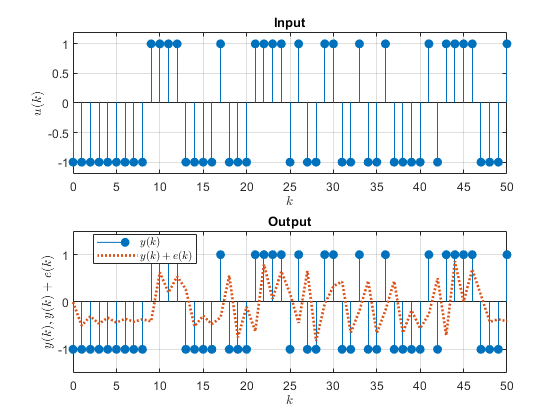

mysys

**Figura 1:** Sinais de saída $y(t)$ e de entrada $u(t)$ do sistema *output-error* simulado.

O sistema estimado via método PEM (*predictor error model*) não linear - conforme descrito nas atividades anteriores - resulta no seguinte vetor $\theta$:

myPEM

Real values 
 > [b1 b2 f1] = [0.50 0.20 0.80]
PEM estimated 
 > [b1 b2 f1] = [0.51 0.16 0.78]


Observando o resultado acima é evidente que o resultado se aproxima dos valores reais. No entanto, não é possível estimar o erro de medição $\sigma_e^2$. Esse parâmetro pode ser estimado pelo método de Bayes com MCMC, o qual resulta no seguinte vetor de parâmetros:

mcmc_oe

Real values 
 > [b1 b2 f1 s0] = [0.50 0.20 0.80 0.84]
MCMC estimated 
 > [b1 b2 f1 s0] = [0.52 0.17 0.80 0.83]
 > dev([b1 b2 f1 s0]) = [0.05 0.04 0.01 0.23]
Acceptance rate: 99.15


A proximidade do resultado acima com o valor real de $\theta$ aponta que o método de Bayes também é adequado para estimação de uma planta cuja saída é contaminada por um erro de medição. Entanto, o desvio padrão atinge até 20% do valor real em relação a $b_2$, o que pode ser atribuído por má sintonia do valor $\sigma_\varepsilon^2$ do passo aleatório incremental. 

Na Figura 2, estão ilustrados os histogramas do valor relativo das amostras candidatas para cada componente do vetor $\theta$. Assim como a conclusão anterior, o deslocamento da distribuição em torno de $1$ é justificada pelos valores de $\sigma_\varepsilon^2$ para cada variável no vetor $\theta$.

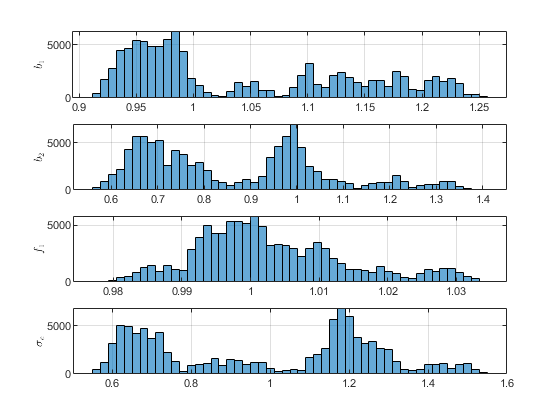

myresults1

**Figura 2:** Histograma dos valores candidatos para as variáveis $b_1$, $b_2$, $f_1
$ e $\sigma_e$.

Observando a Figura 2, é evidente que as estimativas de $b_1$ e $f_1
$ se concentram em torno de um valor central para $K=10^4$ realizações. Entretanto, o mesmo não ocorre para a distribuição de probabilidade das estimativas de $b_2$ e $\sigma_e$. Na Figura 3, estão apresentadas as amostras candidatas para cada componente do vetor $\theta$.

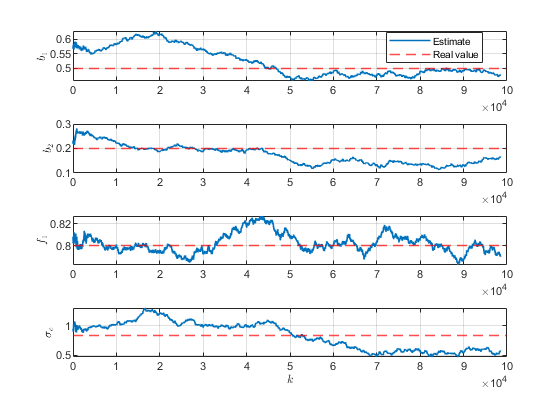

myresults2

**Figura 3:** Evolução dos valores candidatos para as variáveis $b_1$, $b_2$, $f_1
$ e $\sigma_e$.

Observando na Figura 3, as amostras candidatas de $b_2$ e $\sigma_e$ finalizam as $K$ iterações com um erro não nulo em relação ao valor real. Esse resultado pode ser atribuído a má sintonia do passo aleatório $\sigma_\varepsilon$ ou a  largura do período de *burn-in*. Ambas as variáveis impactam o resultado do método, uma vez que determinam a variação das amostras candidatas para o algoritmo de Metropolis-Hastings.

## **Referências bibliográficas**

[1] L. LJUNG. **System Identification: Theory for the User**. Pearson, 1998. 2nd edition, ISBN 9788131744956.

[2] B. KENG. **Markov chain Monte Carlo methods, rejection sampling and the metropoli**. Bounded Rationality. Acesso em 27 de novembro, 2021 ([https://bjlkeng.github.io/posts/markov-chain-monte-carlo-mcmc-and-the-metropolis-hastings-algorithm/](https://bjlkeng.github.io/posts/markov-chain-monte-carlo-mcmc-and-the-metropolis-hastings-algorithm/)).

[3] H. AIT SAADI, F. YKHLEF, E A. GUESSOUM. **MCMC for parameters estimation by Bayesian approach**. Eighth International Multi-Conference on Systems, Signals & Devices. IEEE, mar. 2011. DOI: 10.1109/ssd.2011.5767395.